1D-Filterung

Zeitberecih oder eine Grauwert-Profillinie

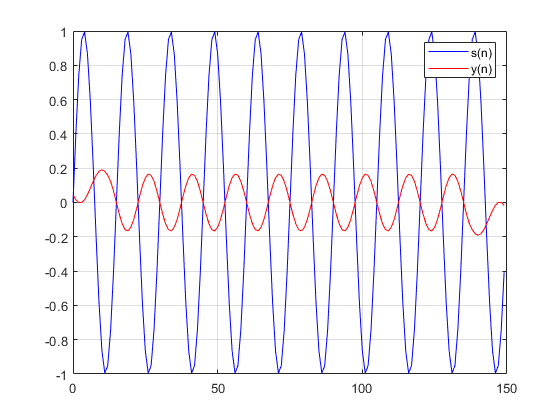

P = 10;
N = 15;
vN = 0:P*N-1; %Index (für Zeitsignale event die Zeit)
f = 1/N; %Frequenz (Ortsfrequenz)
vS = sin(2*pi*f*vN); %Eingangssignal

%tem(vN, vS), grid on, xlabel('n'), ylabel('s(n)')
L = 25;
vH = ones(L, 1);
vH = vH / sum(vH);
vY = conv(vS, vH, 'same');
plot(vN, vS, 'b-'), grid on, hold on
plot(vN, vY, 'r-'), grid on, legend('s(n)', 'y(n)');

Impulsantwort(Filterkoeffizienten) & Frequenzgang

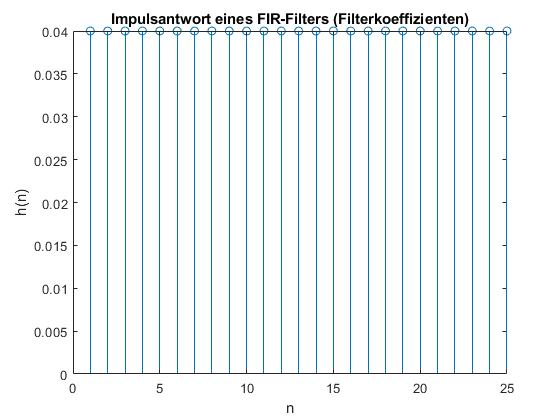

figure,
stem(vH), title('Impulsantwort eines FIR-Filters (Filterkoeffizienten)')
xlabel('n'), ylabel('h(n)')

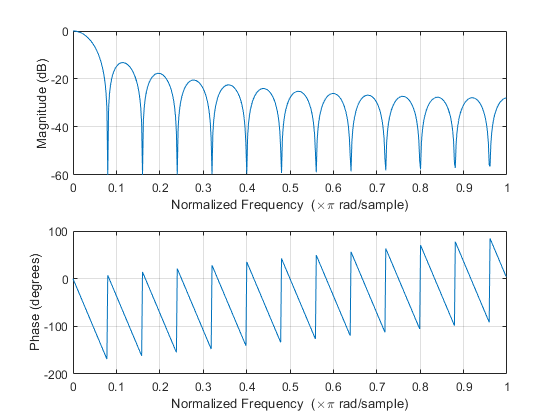

freqz(vH)